# **Dabrowska Data Tutorial (Getting Started)**

Below, you will find a quick tutorial to view the electrophysiology and behavioral data which relates to:

- Paper: [https://doi.org/10.1016/j.celrep.2025.115768](https://doi.org/10.1016/j.celrep.2025.115768)

- Dataset: [https://doi.org/10.63884/ndic.2025.jyxfer8m](https://doi.org/10.63884/ndic.2025.jyxfer8m)

## Import the NDI dataset

Define the dataset path and id.

% Choose the folder where the dataset is (or will be) stored
% (e.g. /Users/myusername/Documents/data/)
dataPath = "/Users/jhaley/Documents/MATLAB/data/test";
cloudDatasetId = '67f723d574f5f79c6062389d';
datasetPath = fullfile(dataPath,cloudDatasetId);

### Download or load the NDI dataset 

The first time you try to access the data, it needs to be downloaded from NDI-cloud. This may take a few minutes. Once you have the dataset downloaded, every other time you examine the data you can just load it.

if isfolder(datasetPath)
    % Load if already downloaded
    dataset = ndi.dataset.dir(datasetPath)
else
    % Download
    dataset = ndi.cloud.downloadDataset(cloudDatasetId,dataPath);
end

### Retrieve the NDI session

A dataset can have mulitple sessions, but this has only one. We must retrieve it in order to access the accompanying documents.

% Retrieve the session from this dataset
[session_ref_list,session_list] = dataset.session_list();
session = dataset.open_session(session_list{1});

## View subject summary

Each individual animal is referred to as a **subject** and has a unique alphanumeric `documentID` and `localID` which contains references to the animal's strain, species, genotype, and experiment date. Our database contains documents which store metadata about each **subject** including their species, strain, genetic strain type, and biological sex which are linked to well-defined ontologies such as [NCBI](https://www.ncbi.nlm.nih.gov/Taxonomy/Browser/wwwtax.cgi?mode=Info&id=10116&lvl=3&lin=f&keep=1&srchmode=1&unlock), [RRID](https://rgd.mcw.edu/rgdweb/report/strain/main.html?id=13508588), and [PATO](https://www.ebi.ac.uk/ols4/ontologies/pato/classes/http%253A%252F%252Fpurl.obolibrary.org%252Fobo%252FPATO_0000384). A summary table showing the metadata for each subject can be viewed below.

% View summary table of all subject metadata
subjectSummary = ndi.fun.subjectDocTable(session)

subjectSummary = 180×14 table
                 documentID                                             localID                                    SpeciesName           SpeciesOntology             StrainName                      StrainOntology                GeneticStrainTypeName    GeneticStrainTypeOntology    BiologicalSexName    BiologicalSexOntology                    stimulatorName                     stimulatorType                                      mfdaqName                                            mfdaqType      
    _____________________________________    _____________________________________________________________    _____________________    ___________________    

## Plot electrophysiology data

Each **subject** is associated with a set of experimental **epochs.** One **epoch** corresponds to one of the original `.mat` files. Select a **subject** from the dropdown control below to view that subject's **epochs** and the associated stimulus conditions for each epoch.

% Select a subject
subjectDocumentID = subjectSummary.documentID;
subjectLocalID = subjectSummary.localID;
subjectName = subjectLocalID(130);
subjectIndex = strcmpi(subjectLocalID,subjectName);

% Get the stimulator probe
stimulator = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','stimulator');
stimulator = stimulator{1}; % one stimulator probe per subject
stimulatorID = stimulator.identifier;

% Get the patch-Vm probe
patchVm = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','patch-Vm');
patchVm = patchVm{1};

% Get the patch-I probe
patchI = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','patch-I');
patchI = patchI{1};

% Get the epochtable associated with the stimulator
epochtable = stimulator.epochtable;

% Retrieve the stimulus_bath metadata
queryDocType = ndi.query('','isa','stimulus_bath');
queryStimulator = ndi.query('','depends_on','stimulus_element_id',stimulatorID);
stimulusBathDocs = session.database_search(queryDocType & queryStimulator);

% Retrieve the stimulus_approach metadata
queryDocType = ndi.query('','isa','openminds_stimulus');
queryStimulator = ndi.query('','depends_on','stimulus_element_id',stimulatorID);
stimulusApproachDocs = session.database_search(queryDocType & queryStimulator);

% Get stimulus_bath mixture and approach for each epoch
mixtureMapPath = fullfile(ndi.common.PathConstants.RootFolder,...
    '+ndi','+setup','+conv','+dabrowska','dabrowska_mixtures.json');
getEpochIndex = @(docs,id) strcmpi(id,cellfun(@(d) d.document_properties.epochid.epochid,docs,'UniformOutput',false));
epochMixtures = cell(size(epochtable));
epochApproach = cell(size(epochtable));
for i = 1:numel(epochtable)

    % Get indices corresponding to current epoch
    epochID = epochtable(i).epoch_id;
    bathIndex = getEpochIndex(stimulusBathDocs,epochID);
    approachIndex = getEpochIndex(stimulusApproachDocs,epochID);
    
    % Get mixture name(s)
    mixture = stimulusBathDocs{bathIndex}.document_properties.stimulus_bath.mixture_table;
    mixture = ndi.database.fun.readtablechar(mixture,'.txt','Delimiter',',');
    mixtureNames = ndi.fun.stimulus.findMixtureName(mixtureMapPath,table2struct(mixture));
    epochMixtures(i) = join(mixtureNames,',');
    
    % Get approach name(s)
    if ~isempty(stimulusApproachDocs)
        epochApproach{i} = stimulusApproachDocs{approachIndex}.document_properties.openminds.fields.name;
    else
        epochApproach{i} = 'N/A';
    end
end

% Display bath mixtures and approaches for each epoch
epochNums = [epochtable.epoch_number];
epochConditions = cell2table([num2cell(epochNums)',epochMixtures',epochApproach'],...
    'VariableNames',{'epochNum','bathCompounds','approach'})

epochConditions = 24×3 table
    epochNum    bathCompounds                    approach                
    ________    _____________    ________________________________________

        1       {'aCSF,OTA'}     {'Approach: Before optogenetic tetanus'}
        2       {'aCSF,OTA'}     {'Approach: Before optogenetic tetanus'}
        3       {'aCSF,OTA'}     {'Approach: Before optogenetic tetanus'}
        4       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
        5       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
        6       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
        7       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
        8       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
        9       {'aCSF,OTA'}     {'Approach: After optogenetic tetanus' }
       10       {'aCSF,OTA'}     {'Approach: After opt

Select an **epoch** to view  **subject** from the dropdown control below to view that subject's **epochs** and the associated stimulus conditions for each epoch.

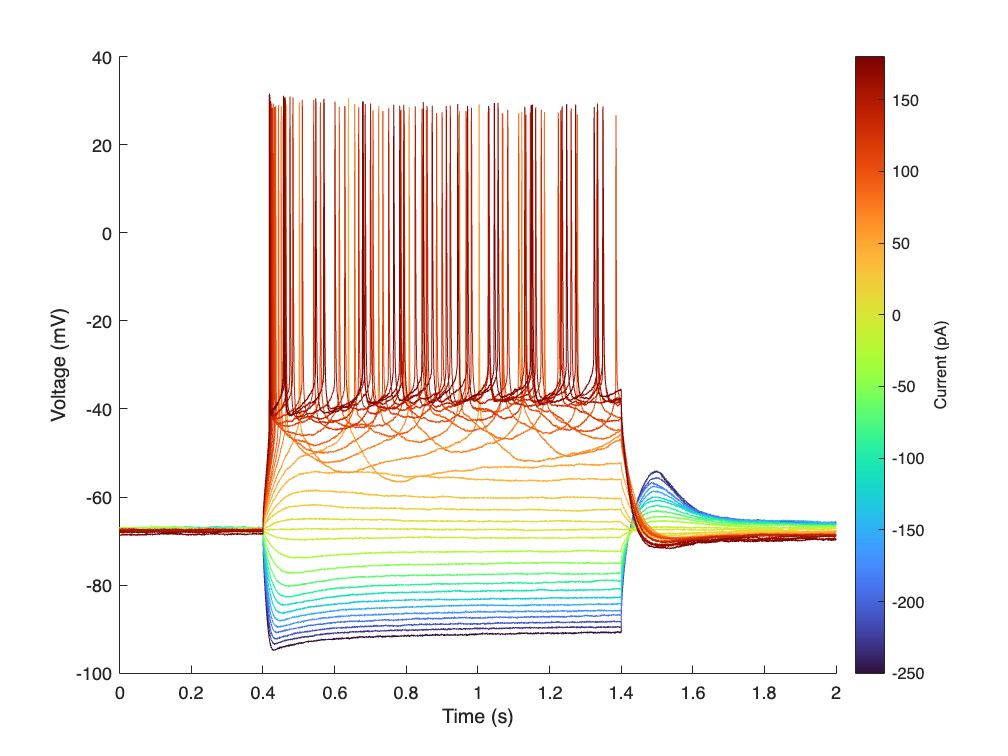

% Select an epoch
epochNum = epochNums(10);

% Read the patch-Vm timeseries
[dataVm,time] = patchVm.readtimeseries(epochNum,-inf,inf);

% Read the patch-I timeseries
[dataI,~] = patchI.readtimeseries(epochNum,-inf,inf);

% Find indices where traces start and end
traceStarts = find(diff([1;isnan(dataI)]) == -1);
traceEnds = find(diff([isnan(dataI);0]) == 1);

% Get number of current steps and number of timepoints per step
numSteps = numel(traceStarts);
numTimepoints = max(traceEnds - traceStarts) + 1;

% Reformat data into a matrix (time x steps)
timeMatrix = time(1:numTimepoints);
dataVmMatrix = nan(numTimepoints,numSteps);
dataIMatrix = nan(numTimepoints,numSteps);
for i = 1:numSteps
    dataVmMatrix(:,i) = dataVm(traceStarts(i):traceEnds(i));
    dataIMatrix(:,i) = dataI(traceStarts(i):traceEnds(i));
end

% Get current step values
[~,rowInd] = max(abs(dataIMatrix));
colInd = 1:size(dataIMatrix,2);
ind = sub2ind(size(dataIMatrix),rowInd,colInd);
currentSteps = dataIMatrix(ind);

% Plot reformatted traces
figure; hold on; ax = gca;
colormap(ax, turbo); clim(ax, [min(currentSteps) max(currentSteps)]);
colors = turbo(max(currentSteps) - min(currentSteps) + 1);
for i = 1:size(dataVmMatrix, 2) % Iterate through each column of dataVmMatrix
    colorInd = currentSteps(i) - min(currentSteps) + 1;
    plot(ax,timeMatrix, dataVmMatrix(:, i), 'Color', colors(colorInd, :));
end
xlabel('Time (s)'); ylabel('Voltage (mV)')
cb = colorbar(ax); cb.Label.String = 'Current (pA)';

## Plot Elevated Plus Maze data

% Get Elevated Plus Maze documents/table
query = ndi.query('ontologyTableRow.names','contains_string','Elevated Plus Maze');
docsEPM = session.database_search(query);
tableEPM = ndi.fun.doc.ontologyTableRowDoc2Table(docsEPM);
varEPM = tableEPM.Properties.VariableNames;

% Get list of all variables
[fullNames,shortNames,ontologyNodes] = ...
    ndi.fun.doc.ontologyTableRowVars(session);

Select a variable to view it's definition and plot the data.

% Define grouping and plotting variables
groupingVariable = 'treatmentCNOSalineAdministration';
plottingVariable = varEPM(31);
plottingVariable = plottingVariable{1};

% Look up the variable in the ontology
termIndex = strcmpi(shortNames,plottingVariable);
termID = ontologyNodes{termIndex};
[id,name,prefix,definition,synonyms,shortName] = ...
    ndi.ontology.lookup(termID);

% Get valid row indices
validRows = ~tableEPM.dataExclusionFlag & ...  % missing mCherry expression
    ~isnan(tableEPM.(plottingVariable)); % missing data points

% Display the variable's id, name, definition, and short name
termInfo = cell2table({id,name,definition,shortName}',...
    'RowNames',{'id','name','definition','shortName'},...
    'VariableNames',{'value'})

termInfo = 4×1 table
                                                                                                                                  value                                                                                                                 
                  ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    id            {'EMPTY:00000128'                                                                                                                                                                                                                    }
    name          {'Elevated Plus Maze: closed arm total - percent time during test duration'                                                                      

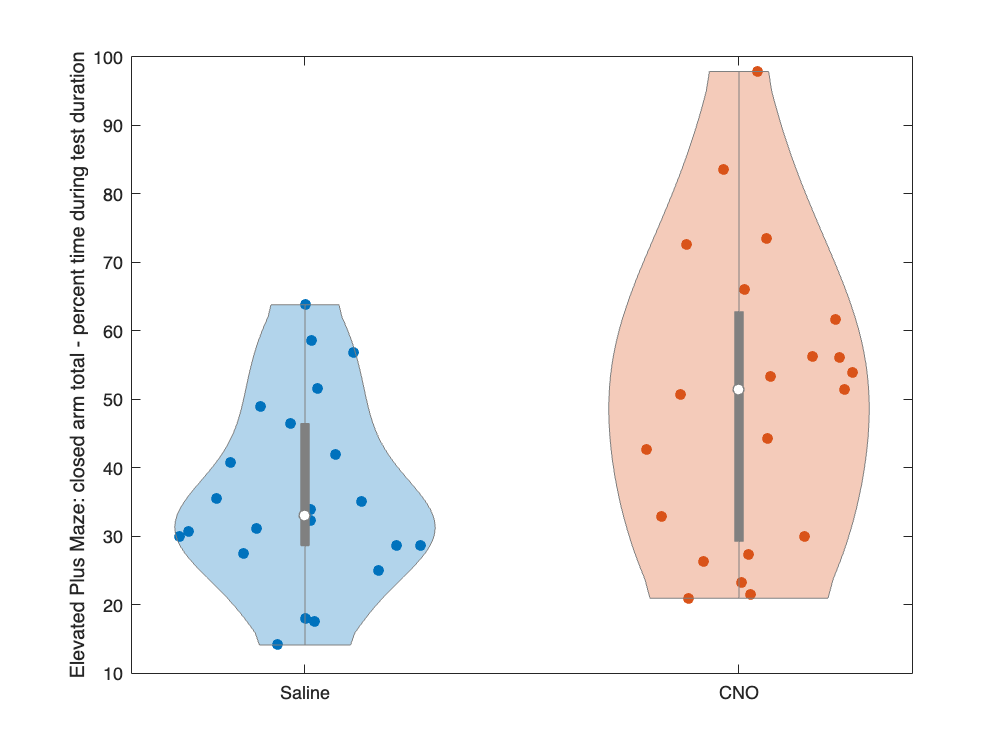

% Plot data
figure;
violinplot(tableEPM{validRows,plottingVariable},...
    categorical(tableEPM{validRows,groupingVariable}),...
    'GroupOrder',{'Saline','CNO'});
ylabel(fullNames{termIndex})

## Plot Fear-Potentiated Startle data

% Get Fear-Potentiated documents/table
query = ndi.query('ontologyTableRow.names','contains_string','Fear-Potentiated Startle');
docsFPS = session.database_search(query);
tableFPS = ndi.fun.doc.ontologyTableRowDoc2Table(docsFPS);

% Get list of all variables
[fullNames,shortNames,ontologyNodes] = ...
    ndi.fun.doc.ontologyTableRowVars(session);

% Get average startle amplitude for each context, subject, and trial
tableStartleAmplitude = groupsummary(tableFPS,...
    {'fpsExperimentalPhaseTestName','subjectLocalIdentifier','fpsTrialTypeIdentifier'},...
    'mean','asrMaximumAmplitude');
experimentalPhases = unique(tableStartleAmplitude.fpsExperimentalPhaseTestName);
experimentalPhases = experimentalPhases(contains(experimentalPhases,'Cue test'));

% Get row indices corresponding to each trial type
lightNoiseRows = strcmpi(tableStartleAmplitude.fpsTrialTypeIdentifier,'FPS (L+N) Testing Trial');
noiseOnlyRows = strcmpi(tableStartleAmplitude.fpsTrialTypeIdentifier,'FPS (N) Testing Trial');
startleRows = strcmpi(tableStartleAmplitude.fpsTrialTypeIdentifier,'Startle 95 dB Trial');

% Get tables of startle amplitude for each trial type
tableLightNoise = tableStartleAmplitude(lightNoiseRows,...
    {'fpsExperimentalPhaseTestName','subjectLocalIdentifier','mean_asrMaximumAmplitude'});
tableNoiseOnly = tableStartleAmplitude(noiseOnlyRows,...
    {'fpsExperimentalPhaseTestName','subjectLocalIdentifier','mean_asrMaximumAmplitude'});
tableStartle = tableStartleAmplitude(startleRows,...
    {'fpsExperimentalPhaseTestName','subjectLocalIdentifier','mean_asrMaximumAmplitude'});

% Rename startle amplitude variable
tableLightNoise = renamevars(tableLightNoise,'mean_asrMaximumAmplitude','startleAmplitudeLightNoise');
tableNoiseOnly = renamevars(tableNoiseOnly,'mean_asrMaximumAmplitude','startleAmplitudeNoiseOnly');
tableStartle = renamevars(tableStartle,'mean_asrMaximumAmplitude','startleAmplitudeStartle');

% Join trial type tables
tableCuedFear = join(tableLightNoise,tableNoiseOnly,...
    'Keys',{'fpsExperimentalPhaseTestName','subjectLocalIdentifier'});
tableCuedFear = join(tableCuedFear,tableStartle,...
    'Keys',{'fpsExperimentalPhaseTestName','subjectLocalIdentifier'});

% Calculate cued fear %
tableCuedFear.cuedFear = 100*(tableCuedFear.startleAmplitudeLightNoise - ...
    tableCuedFear.startleAmplitudeNoiseOnly)./...
    tableCuedFear.startleAmplitudeNoiseOnly; % 100*(LN - N)/N

% Calculate non-cued fear %
tableCuedFear.nonCuedFear = 100*(tableCuedFear.startleAmplitudeNoiseOnly - ...
    tableCuedFear.startleAmplitudeStartle)./...
    tableCuedFear.startleAmplitudeStartle; % 100*(N - S)/S

varFPS = tableCuedFear.Properties.VariableNames;

Select an experimental phase and variable to plot the data.

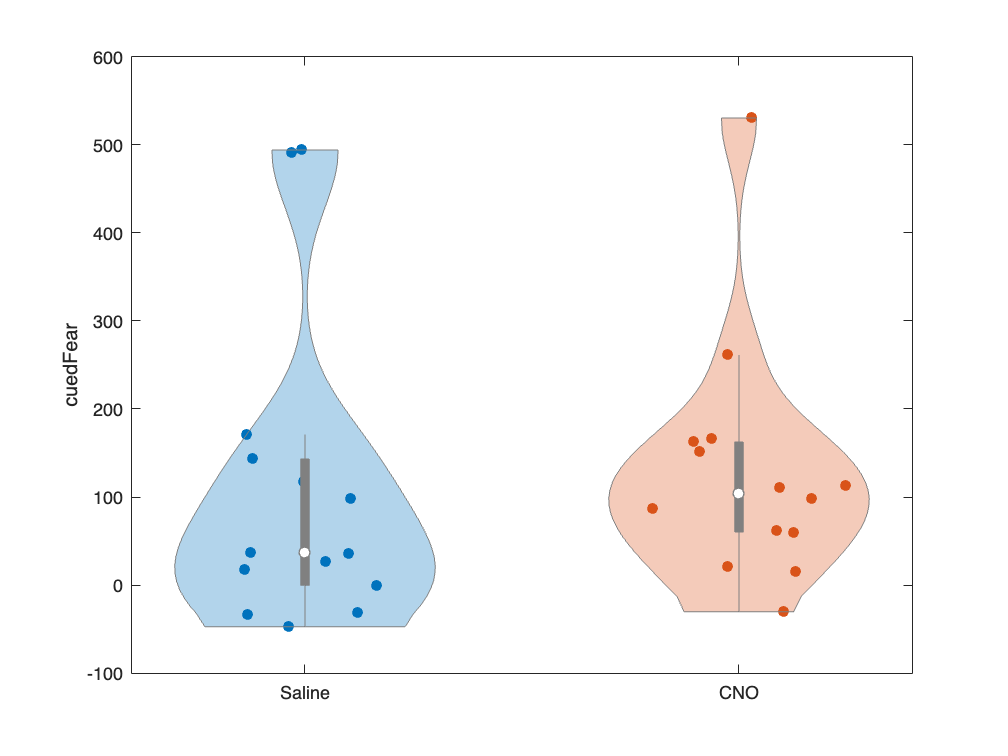

% Choose an experimental phase
experimentalPhase = experimentalPhases(1);

% Define grouping and plotting variables
groupingVariable = 'treatmentCNOSalineAdministration';
plottingVariable = varFPS(6);
plottingVariable = plottingVariable{1};

% Add grouping variable info from EPM table
tableCuedFear = join(tableCuedFear,tableEPM(:,{'subjectLocalIdentifier',groupingVariable}));

% Get row indices corresponding to the experimental phase
phaseRows = strcmpi(tableCuedFear.fpsExperimentalPhaseTestName,experimentalPhase{1});

% Plot cued fear % in first recall (Figure 4D')
figure; violinplot(tableCuedFear{phaseRows,plottingVariable},...
    categorical(tableCuedFear{phaseRows,groupingVariable}),...
    'GroupOrder',{'Saline','CNO'});
ylabel(plottingVariable)